clear; clear path; clc;
cd('~/git/hardDiskControl/continuousTimeControl/distReject/')
load('../../data/plantTF.mat');
addpath ../../funcs/;

xi = 0.690108;
wn = 1;
desiredPoles = [-xi*wn+wn*sqrt(1-xi^2)*1i; -xi*wn- wn*sqrt(1-xi^2)*1i]

desiredPoles =   -0.6901 + 0.7237i
  -0.6901 - 0.7237i


calcDamp(desiredPoles)

ans =     0.7237
   -0.7237


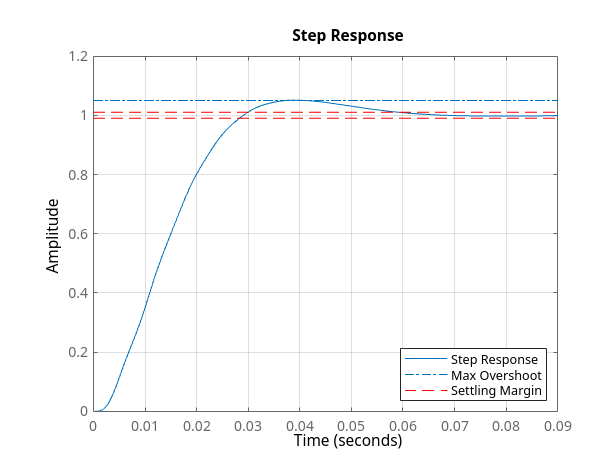


Cs = pidGen(0, 0, 80, 150,1);
% Cs = pidGen(1, .2, 1, 1,1);

figure(1); clf; hold on;
step(Cs*Ps/(1+Cs*Ps))
plot([0 1],[1.05 1.05],'-.')
plot([0 1],[1.01 1.01],'r--')
plot([0 1],[.99 .99],'r--')
legend('Step Response', 'Max Overshoot', 'Settling Margin',"Location",'southeast')
grid on;

poles1 = refPoles(0, 0, 80, 150)

poles1 = 1.0e+02 *

  -0.7593 - 0.7990i
  -0.7593 + 0.7990i
  -0.9907 - 9.8891i
  -0.9907 + 9.8891i


damps1 = calcDamp(poles1)

damps1 =    -0.7249
    0.7249
   -0.9950
    0.9950


wn = abs(poles1)

wn =   110.2210
  110.2210
  993.8623
  993.8623


info = stepinfo(Cs*Ps/(1+Cs*Ps))

info = struct with fields:
         RiseTime: 0.0188
    TransientTime: 0.0543
     SettlingTime: 0.0543
      SettlingMin: 0.9047
      SettlingMax: 1.0513
        Overshoot: 5.1324
       Undershoot: 0
             Peak: 1.0513
         PeakTime: 0.0388


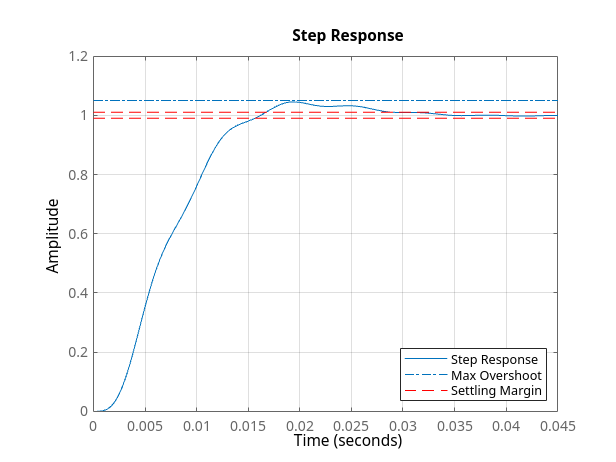




Cs = pidGen(0, 0, 150, 300,1);
figure(1); clf; hold on;
step(Cs*Ps/(1+Cs*Ps))
plot([0 1],[1.05 1.05],'-.')
plot([0 1],[1.01 1.01],'r--')
plot([0 1],[.99 .99],'r--')
legend('Step Response', 'Max Overshoot', 'Settling Margin',"Location",'southeast')
grid on;

poles2 = refPoles(0, 0, 80, 200)

poles2 = 1.0e+02 *

  -1.0165 - 0.7701i
  -1.0165 + 0.7701i
  -0.9835 - 9.8695i
  -0.9835 + 9.8695i


damps2 = calcDamp(poles2)

damps2 =    -0.6039
    0.6039
   -0.9951
    0.9951


wn = abs(poles2)

wn =   127.5318
  127.5318
  991.8400
  991.8400


info = stepinfo(Cs*Ps/(1+Cs*Ps))

info = struct with fields:
         RiseTime: 0.0090
    TransientTime: 0.0272
     SettlingTime: 0.0272
      SettlingMin: 0.9023
      SettlingMax: 1.0453
        Overshoot: 4.5336
       Undershoot: 0
             Peak: 1.0453
         PeakTime: 0.0193
